# Problem 1

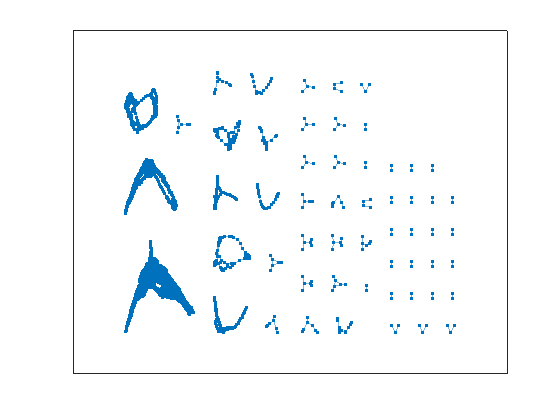

% Loading Data

data = load("usroads.mat");

G = graph(data.Problem.A);
plot(G)

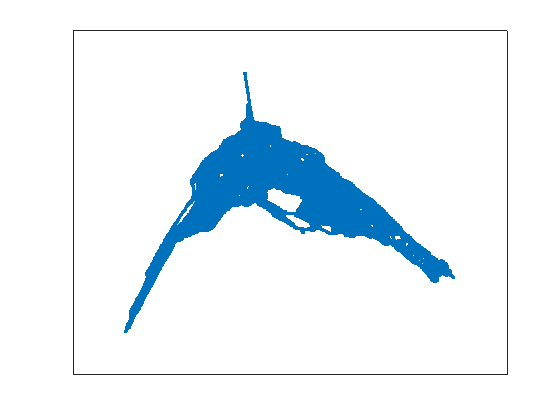

comps = conncomp(G);

SG = subgraph(G, comps==28);
plot(SG)

## Problem 1.1

A_SG = adjacency(SG);

A_SG2 = [0 0 0 0 0 0 0 0 1 0 0 0 0 0 0;
0 0 0 0 0 1 1 0 1 0 0 0 0 0 0;
0 0 0 0 1 0 0 0 1 0 0 0 0 0 0;
0 0 0 0 0 0 1 0 0 0 1 0 0 1 0;
0 0 1 0 0 0 0 0 0 0 1 0 0 1 0;
0 1 0 0 0 0 0 0 0 0 0 0 0 0 0;
0 1 0 1 0 0 0 1 0 0 0 0 0 0 1;
0 0 0 0 0 0 1 0 0 0 0 0 0 0 0;
1 1 1 0 0 0 0 0 0 0 0 1 1 0 1;
0 0 0 0 0 0 0 0 0 0 0 0 1 0 0;
0 0 0 1 1 0 0 0 0 0 0 0 0 1 0;
0 0 0 0 0 0 0 0 1 0 0 0 0 1 1;
0 0 0 0 0 0 0 0 1 1 0 0 0 0 0;
0 0 0 1 1 0 0 0 0 0 1 1 0 0 0;
0 0 0 0 0 0 1 0 1 0 0 1 0 0 0]

A_SG2 =      0     0     0     0     0     0     0     0     1     0     0     0     0     0     0
     0     0     0     0     0     1     1     0     1     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     1     0     0     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     1     0     0     1     0
     0     0     1     0     0     0     0     0     0     0     1     0     0     1     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     1     0     0     0     1     0     0     0     0     0     0     1
     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0
     1     1     1     0     0     0     0     0     0     0     0     1     1     0     1
     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0



A_SG = A_SG./sum(A_SG)

A_SG =                  (17,1)                      1.0000
                 (17,2)                      1.0000
                  (7,3)                      1.0000
                 (62,4)                      1.0000
                 (52,5)                      1.0000
                 (83,6)                      1.0000
                  (3,7)                      0.5000
                 (47,7)                      0.5000
                 (56,8)                      1.0000
                (286,9)                      1.0000
                 (57,10)                     1.0000
                (127,11)                     1.0000
                (188,12)                     1.0000
                (282,13)                     1.0000
                (260,14)                     1.0000
                (243,15)                     1.0000
                (187,16)                     1.0000
                  (1,17)                     0.3333
                  (2,17)                     0.3333
     

## Problem 1.2

% Find the page rank of this network using power iteration.

% Need to find the page rank iteratively since the complete matrix is
% large...
alpha = 0.9;
k = 5;
n = length(A_SG);
%Make a column vector of 1's normalized to n
v = eye(n, 1) / n;

partial = alpha*A_SG*v;

v_sum = v + partial;

for i = 2:k
    partial = alpha*A_SG*partial;
    v_sum = v_sum + partial;
end

x = (1- alpha)*v_sum;
x

x = 1.0e-05 *

    0.1142
    0.0349
         0
    0.0006
         0
         0
         0
         0
         0
         0


sum(x*k)

ans = 1.8572e-05

%pr = ((1-alpha)/n)*pinv(eye(n,n) - alpha*A_SG)*eye(n,1)

### Sensitivity

%todo: Ask professor about sensitivity

k = 5;
n = length(A_SG);

tests = 10;
ranks = zeros(n, tests);
pos = 1;

%Make a column vector of 1's normalized to n
v = eye(n, 1) / n;

partial = A_SG*v;

v_sum = v + 2*partial;

for i = 2:k
    partial = partial * alpha;
    v_sum = v_sum + (1+k)*partial;
end

x = (1- alpha)*v_sum;
ranks(:,pos) = x;
pos = pos + 1;



### Plot Sensitivity

errors =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


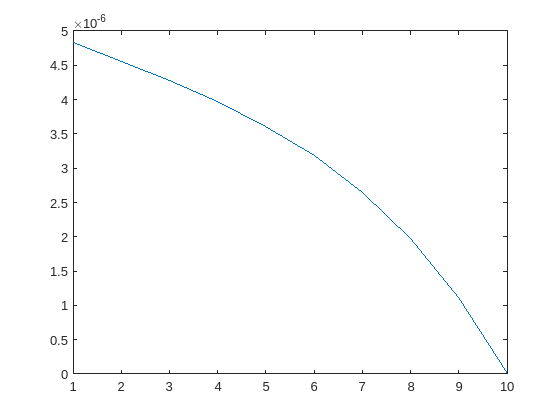

## G49.mat

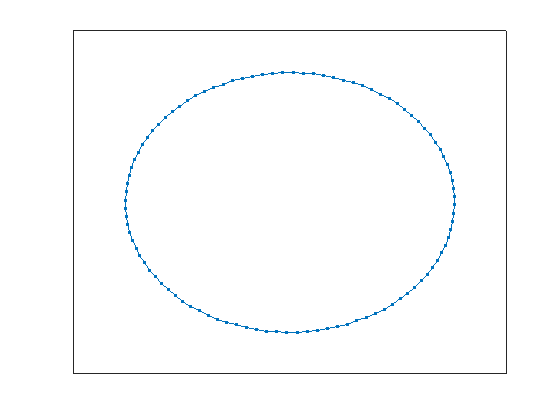

load('G49.mat')

A_G49 = graph(Problem.A);
plot(A_G49)

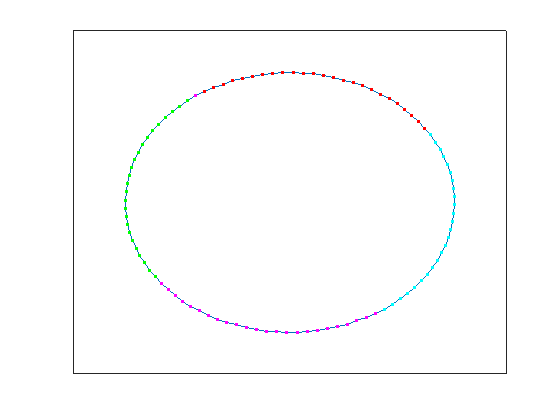

L = laplacian(A_G49);%A_G49*transpose(A_G49)
[D, S] = eigs(L, 3000);

Positions = 1:3000;

s = diag(S);

%Find the minimum of S that isn't ~zero
[M, I] = min(s(abs(s) > 1e-15));

Cut = D(:,I) > 0;

H1_nodes = Positions(Cut);
H2_nodes = Positions(~Cut);

H1 = rmnode(A_G49, H1_nodes);
H2 = rmnode(A_G49, H2_nodes);

G_plot = plot(A_G49);
highlight(G_plot,H1_nodes,'NodeColor','g');
highlight(G_plot,H2_nodes,'NodeColor','r');

% Split the first half in two
L1 = laplacian(H1);
n1 = height(H1.Nodes);
[D1, S1] = eigs(L1, n1);

Pn1 = 1:n1;

s1 = diag(S1);

%Find the minimum of S that isn't ~zero
[M1, I1] = min(s1(abs(s1) > 1e-10));

Cut1 = D1(:,I1) > 0;

H11 = rmnode(H1, Pn1(~Cut1));
H12 = rmnode(H1, Pn1(Cut1));

H11_nodes = H1_nodes(Cut1);
H12_nodes = H1_nodes(~Cut1);

highlight(G_plot,H11_nodes,'NodeColor','magenta');

% Split the second half in two
L2 = laplacian(H2);
n2 = height(H2.Nodes);
[D2, S2] = eigs(L2, n2);

Pn2 = 1:n2;

s2 = diag(S2);

%Find the minimum of S that isn't ~zero
[M2, I2] = min(s2(abs(s2) > 1e-10));

Cut2 = D1(:,I2) > 0;

H21 = rmnode(H2, Pn2(~Cut2));
H22 = rmnode(H2, Pn2(Cut2));

H21_nodes = H2_nodes(Cut2);
H22_nodes = H2_nodes(~Cut2);

highlight(G_plot,H21_nodes,'NodeColor','cyan');

### Find the Dirichlet PageRank